# Local Histogram Equilization

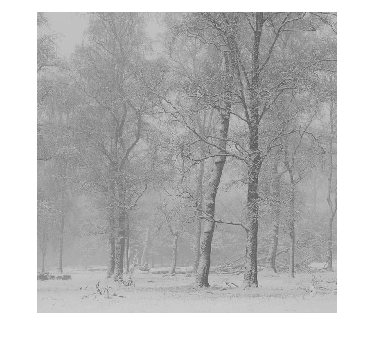

% defining the necessary constants and importing the images
w_r_n = 51;
w_c_n = 51; % means window row numbers and column numbers(size of window)
center_to_end_vertical = (w_r_n - 1)/2;
center_to_end_horizontal = (w_c_n - 1)/2;
im = imread('LC2.jpg');
imshow(im);

[rnum, cnum] = size(im);

### Normalised Histogram's Weight Calculating Function

%Function that would return normalized histogram density values, given a list containing Intensity values
function [norm_intensity_density] = norm_hist_density_calculator(intensity_list)
    list_size = size(intensity_list);
    num_elements = list_size(2);
    unnorm_intensity_density = zeros(1,256); % contains how frequent each intensity occurs
    for i =1:num_elements
        intensity_value = intensity_list(i)+1;
        unnorm_intensity_density(intensity_value) = unnorm_intensity_density(intensity_value) + 1; 
    norm_intensity_density = unnorm_intensity_density/num_elements;
    end
end

### Implementing Local Histogram Equilization

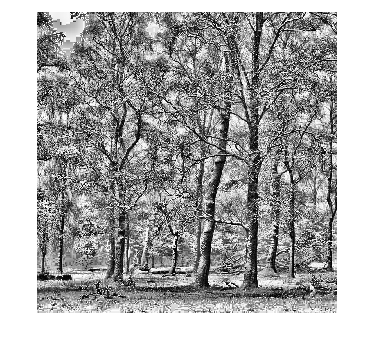

mod_im = zeros(rnum, cnum);
for i = 1:rnum
    for j = 1:cnum
        available_intensity = [];
        intensity_value_ij = im(i,j);
        for x = i-center_to_end_vertical:i+center_to_end_horizontal
            for y = j - center_to_end_horizontal: j+center_to_end_horizontal
                if ((1<=x)&&(x<=rnum))&&((1<=y)&&(y<=cnum))
                    available_intensity = [available_intensity, im(x, y)];
                end
            end
        end
        norm_int_dens = norm_hist_density_calculator(available_intensity);
        cdf_value = sum(norm_int_dens(1:intensity_value_ij+1));
        modified_instensity = cdf_value*255;
        mod_im(i, j) = modified_instensity;
    end
end
mod_im = uint8(mod_im);
imshow(mod_im);

imwrite(mod_im, 'LC2_window_size51_51.jpg');